# Tarea 2

## Macroeconomia I

1.- en un pais X,que crece de acurdo a un modelo de solow sin productividad

deprec = 0.04;
s = 0.2;
w =[1.04 0.9];
pi_0=[0.9 0.1];
P=[0.9 0.1;0.8,0.2]; %matriz de trans
T_ = 1100; %longitud de la cadena
Ezt = (0.9*1.04+ 0.1*0.9 + 0.8*1.04+0.2*0.9)/2

Ezt = 1.0190

a) Este modelo tiene una funcion de produccion $f(k_y) = z_t k^{ 0,3}$ donde $z_t$ es una variable aleatoria que sigue una cadena de markov. 

por esto, en lugar de un estado estacionario $k^{ss}$, se puede encontrar un sendero de crecimiento balanceado; una tendencia que el modelo seguira mas solo converge en probabilidad. 

este estado sera tal que 


$$k_{t+1} = (1- \delta)*k_{t} + s*f (k_t)$$


y $k_{t+1} =k_t$

por lo que  $k =(1- \delta)k +s z_t k^{0,3}$


$$1 =(1-\delta) +sE(z_t) k^{0.3-1}$$



$$k^{ss} = (\frac{1-(1-\delta)}{sE(z_{t})})^{\frac{1}{0.3-1}}$$



$$k^{ss} = (\frac{\delta}{sE(z_{t})})^{\frac{-1}{0.7}$$



$$k^{ss} = (\frac{0.04}{0.2*E(z_{t})})^{-1/0.7}$$


Ekss = ((deprec)/s*Ezt)^(-1/0.7)

Ekss = 9.7018

kss1 = ((deprec)/s*1.04)^(-1/0.7)

kss1 = 9.4231

kss1 = ((deprec)/s*0.9)^(-1/0.7)

kss1 = 11.5850

b)

K = zeros(T_, 1); %vector de valores de capital
Z = zeros(T_,1); %Vector de resultados de la cadena
E = zeros(T_, 1); %Vector de estados
R = zeros(T_, 1); %Vector de recesion
shock = rand(size(Z)); %condicionador de error

Z(1)=(shock(1)<pi_0(1))*w(1) + (shock(1)>=pi_0(1))*w(2);
E(1) = (shock(1) < pi_0(1))*1 +(shock(1)>=pi_0(1))*2;
K(1)=Z(1);
R(1)=E(1)

R =      2
     0
     0
     0
     0
     0
     0
     0
     0
     0


for t = 2:T_
    estado_1 = E(t-1);
    if estado_1 == 1
        Z(t) = ((shock(t)<P(1,1))*w(1)) + ((shock(t)>=P(1,1))*w(2));
        E(t) = ((shock(t)<P(1,1))*1) +((shock(t) >= P(1,1))*2);
        R(t) = 0;
    else
        Z(t) = ((shock(t)<P(2,1))*w(1)) + ((shock(t)>=P(2,1))*w(2));
        E(t) = ((shock(t)<P(2,1))*1) + ((shock(t)>= P(2,1))*2);
        R(t) = R(t-1)+1;
    end
    K(t) = (Z(t)*K(t-1)^(0.3))*s + (1-deprec)*K(t-1);
end

R =      2
     3
     0
     0
     0
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     0
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     0
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R =      2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


R = 10×1
     2
     3
     0
     0
     1
     0
     0
     0
     0
     0


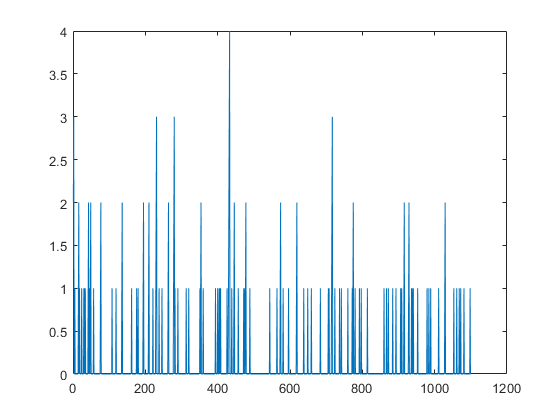

plot((1:1:T_),R)

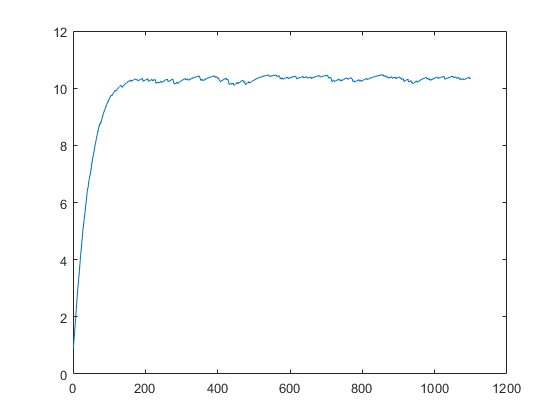

plot((1:1:T_),K)

2. con $f(k_t) = k_t - \frac{k_t^3}{3}$,

a) la funcion de equilibrio es tal que el cambio de $k_t$ a $k_{t+1}$ es cero. 


$$\Delta k_t = (1-\delta) +(1-\frac{2}{3}k)s =0$$



$$1-\delta +s =\frac{2}{3}ks$$



$$k^{ss} = \frac{3}{2}(\frac{1}{s}-\frac{\delta}{s} +1)$$


b) con los valores dados, $k_1 = \frac{1}{2}*(1-\frac{1}{3})+(1-0.25)$= $\frac{13}{12}$ = 1.083, o sea, un aumento de 0.083 unidades de capital. 

Ocupando la ecuacion de $k^{ss}$, 


$$k^{ss} =  \frac{3}{2}(2-\frac{0.25}{0.5} +1)=1.5$$


c)

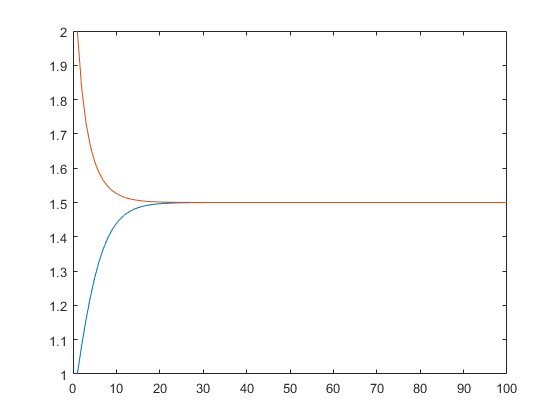

K2 = zeros(100,1);
K3 = zeros(100,1);
K2(1) = 1;
K3(1)=2;
for t = 2:100
    K2(t) = 0.5*(K2(t-1)-((K2(t-1))^2/3))+(0.75)*K2(t-1);
    K3(t) = 0.5*(K3(t-1)-((K3(t-1))^2/3))+(0.75)*K3(t-1);
end
plot(K2)
hold on
plot(K3)
hold off